# Sample dataset: Back pain clinical trial

We'll load and examine a sample dataset. This dataset is from:

Ashar et al. 2022, JAMA Psychiatry

This study is a randomized clinical trial (RCT) of patients with chronic back pain (>= 4/10 pain for at least 3 months, average duration ~10 years). The trial compares Pain Reprocessing Therapy, Placebo (a single injection into the skin of the back), and Usual Care treatments, with pre-treatment and post-treatment (1 month after treatment initiation), and follow-up to 1 year. 

**Prep and Examine the dataset**

#### Dependencies and setup

Do you have the relevant files on your Matlab path?  

which Ashar2022_outcomes_demographics.csv

/Users/f003vz1/Dropbox (Dartmouth College)/COURSES/Courses_Dartmouth/2023_Fall_Computational_Foundations/Datasets/Ashar_2022_PRT_backpain/Ashar2022_outcomes_demographics.csv


If you get an error, you don't!  

You also need the Statistics and Machine Learning Toolbox in Matlab. Try this to check:

if isempty(ver('stats')), warning('You do not have the statistics toolbox on your Matlab path. You may/will get errors'); end

#### **Load the dataset**

We'll read the dataset from a Comma Separated Value (csv) file into a **table** object. **Table** is a Matlab class that is very convenient, as it: 

(1) stores *metadata* like table names and descriptions, and 

(2) has associated *methods* for manipulating the dataset (e.g. selecting cases, etc.)

In addition, some statistics functions (like *fitlme*, for mixed effect models) can take table objects directly, allowing you to reference variables by name 

backpain_all = readtable('Ashar2022_outcomes_demographics.csv');

backpain_all  % print (some of) the table to screen

backpain_all = 341×35 table
    id    time    group    pain_avg    bpi_intensity    bpi_interference    odi    promis_dep    promis_anger    promis_anxiety    promis_sleep    panas_pa    panas_na    pcs    tsk11    sopa_emo    pgic    tx_satisfaction    alcohol    opioid    cannabis    education    ethnicity    hispanic    employment_status    exercise    handedness    sses    married_or_living_as_marri    age    weight    gender    current_opi

#### Examine some of the key variables

**It's always critical to look at your data!  **Check that the distributions and values make sense.

We'll work with a few key variables, though there are many more interesting ones to examine!

backpain_all.id;                             **Subject ID**

backpain_all.time;                         **Assessment time** (1 = pre-treatment, 2 = post)

backpain_all.group;                      **Treatment group** (1 = PRT, 2 = Placebo, 3 = Usual Care,             

                                                     NaN = Healthy (nonpatient, not randomized)

backpain_all.bpi_intensity;           **Primary outcome**, pain intensity

backpain_all.gender;                    **Sex/gender** (not diff here; 1 = male, 2 = fem, 3 = other)

logical(backpain_all.is_patient);   1 = patient, 0 = healthy control (not randomized/treated)

**How many subjects?**

length(unique(backpain_all.id))

ans = 206

**How many patients?**

is_patient = logical(backpain_all.is_patient); % 1 = patient, 0 = healthy control (not randomized/treated)
length(unique(backpain_all.id(is_patient)))

ans = 152

**Calculate descriptive stats for all variables, and view stats for "group"**

descriptive_stats = summary(backpain_all);
descriptive_stats.group

ans = struct with fields:
           Size: [341 1]
           Type: 'double'
    Description: ''
          Units: ''
     Continuity: []
            Min: 1
         Median: 2
            Max: 3
     NumMissing: 55


**How many subjects assessed per group and time point?**

% Tabulate two variables
tab = crosstab(backpain_all.group, backpain_all.time);

tab =     50    44
    51    44
    50    47



% Print the results with labels (and save table object in tab)
tab = table(tab(:, 1), tab(:, 2), 'VariableNames',{'T1' 'T2'}, 'RowNames', {'PRT' 'Placebo' 'Control'})

tab = 3×2 table
               T1    T2
               __    __

    PRT        50    44
    Placebo    51    44
    Control    50    47


**Create a smaller, reduced dataset with only a few variables we need**

This is called backpain_stacked because the dataset is "stacked" in "long form", with multiple rows per participant.  This is a *repeated measures design*, and participants thus have a row for each visit ("Time 1" pre-treatment and "Time 2" post-treatment).

Long-format is convenient for storing a dataset in a single frame and for mixed effects models, which keep track of which observations are collected on the same participants (and other dependencies) internally.  

This has patients only, because the controls have NaN values for group.

backpain_stacked = backpain_all(:, {'id' 'time' 'group' 'bpi_intensity' 'gender' 'is_patient'})

backpain_stacked = 341×6 table
    id    time    group    bpi_intensity    gender    is_patient
    __    ____    _____    _____________    ______    __________

    12     1        3           2.5           1           1     
    12     2        3          2.75           1           1     
    14     1        3           2.5           2           1     
    14     2        3             2           2           1     
    15     1        3          2.25           1           1     
    15     2        3          2.75           1           1     
    18     1        2           4.5           1           1     
    18     2        2          2.25           1           1     
    23     1        2           2.5           2           1     
    23     2        2          2.25           2  

**Unstack the dataset to match outcome values within-person**

For standard single-level GLMs and repeated measures models (paired t-tests, repeated measures ANOVA), the "long format" dataset is inappropriate. We want a "wide format" dataset, with one row per person, and repeated measures from the person in different variables (columns). 

backpain = unstack(backpain_stacked,'bpi_intensity','time', 'NewDataVariableNames', {'BPI_Time1', 'BPI_Time2'})

backpain = 151×6 table
    id    group    gender    is_patient    BPI_Time1    BPI_Time2
    __    _____    ______    __________    _________    _________

    12      3        1           1            2.5         2.75   
    14      3        2           1            2.5            2   
    15      3        1           1           2.25         2.75   
    18      2        1           1            4.5         2.25   
    23      2        2           1            2.5         2.25   
    24      1        1           1            4.5          0.5   
    29      1        2           1           3.75         0.25   
    32      1        1           1           5.75         0.25   
    38      1        2           1            5.5         1.75   
    51      2        1           1            

Now, rows correspond to participants, and columns correspond to measured variables.

Missing data are coded with NaN (Not a Number), so participants who are missing a time point will have NaN values for that time point. 

Let's add a column for the change in pain (improvement), where negative values mean more improvement:

backpain.BPI_change = backpain.BPI_Time2 - backpain.BPI_Time1;


**Create sub-tables with only participants in each group**

We do this for convenience, so we can extract data and plot it easily.

prt = backpain(backpain.group == 1, :);
placebo = backpain(backpain.group == 2, :);
control = backpain(backpain.group == 3, :);


Save simple tables

We can save simple versions of the tables for later, so that we can download and work with them in any software package.

### Visualize the data

Let's create some plots of the improvement in BPI (Brief Pain Inventory) by group

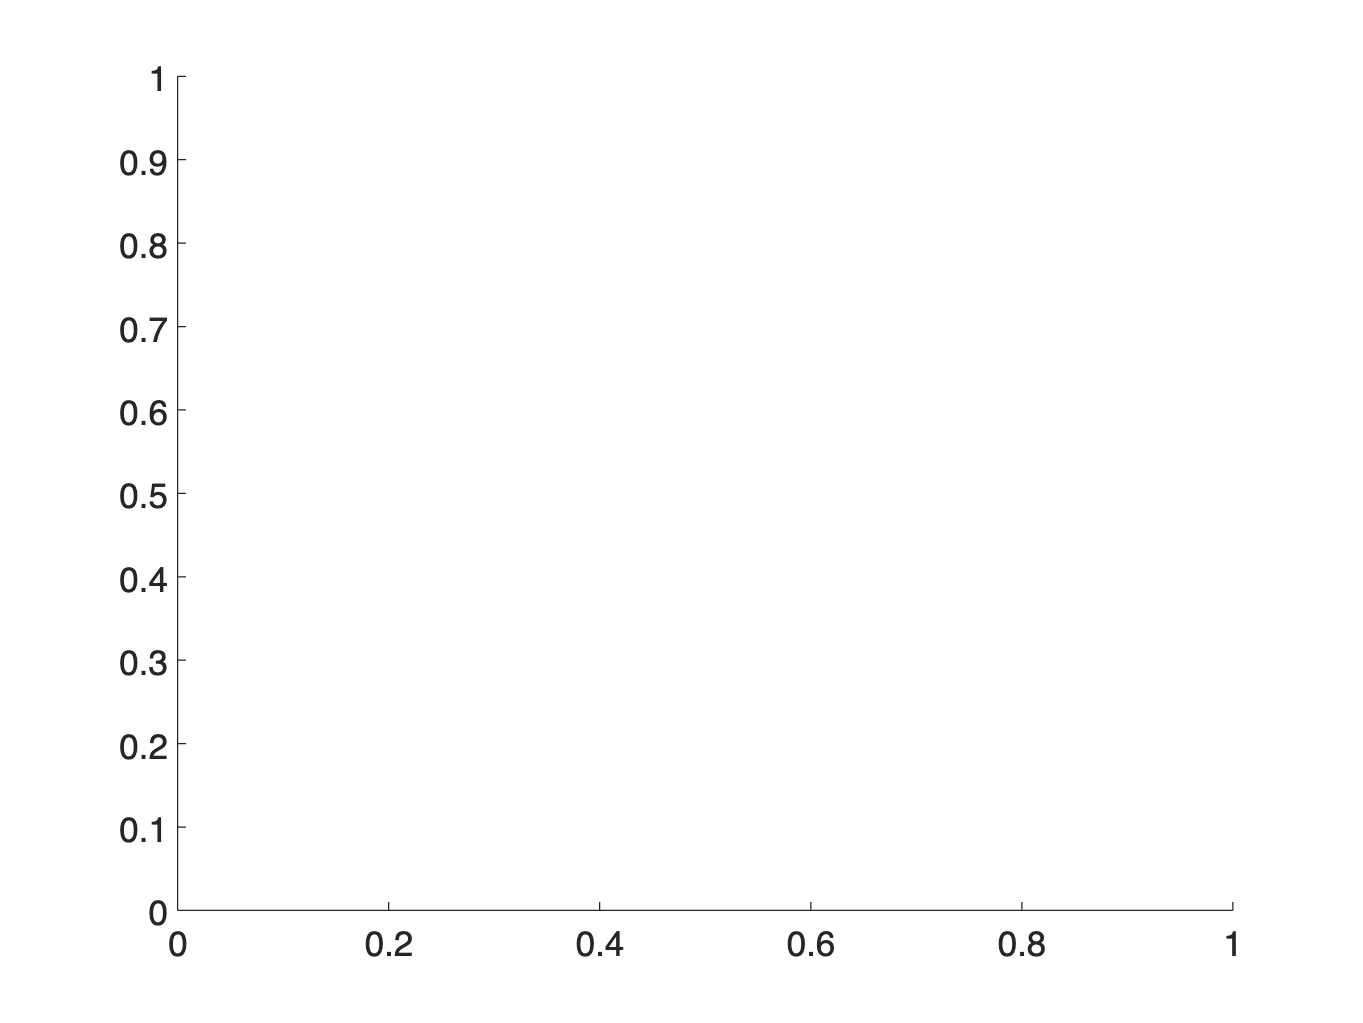


data_to_plot = {prt.BPI_change, placebo.BPI_change, control.BPI_change};
colors = seaborn_colors(3);

create_figure('Violins');

barplot_columns(data_to_plot, 'Improvement by group', 'colors', colors, 'names', {'PRT', 'Placebo' 'Control'});

Col   1: PRT	Col   2: Placebo	Col   3: Control	
---------------------------------------------
Tests of column means against zero
---------------------------------------------
       Name        Mean_Value    Std_Error       T           P         Cohens_d
    ___________    __________    _________    _______    __________    ________

    {'PRT'    }      -2.6648      0.21657     -12.304    2.2204e-15     -1.8549
    {'Placebo'}     -0.89773      0.18523     -4.8466    1.6705e-05    -0.73065
    {'Control'}     -0.51596       0.1531     -3.3701     0.0015294    -0.49158



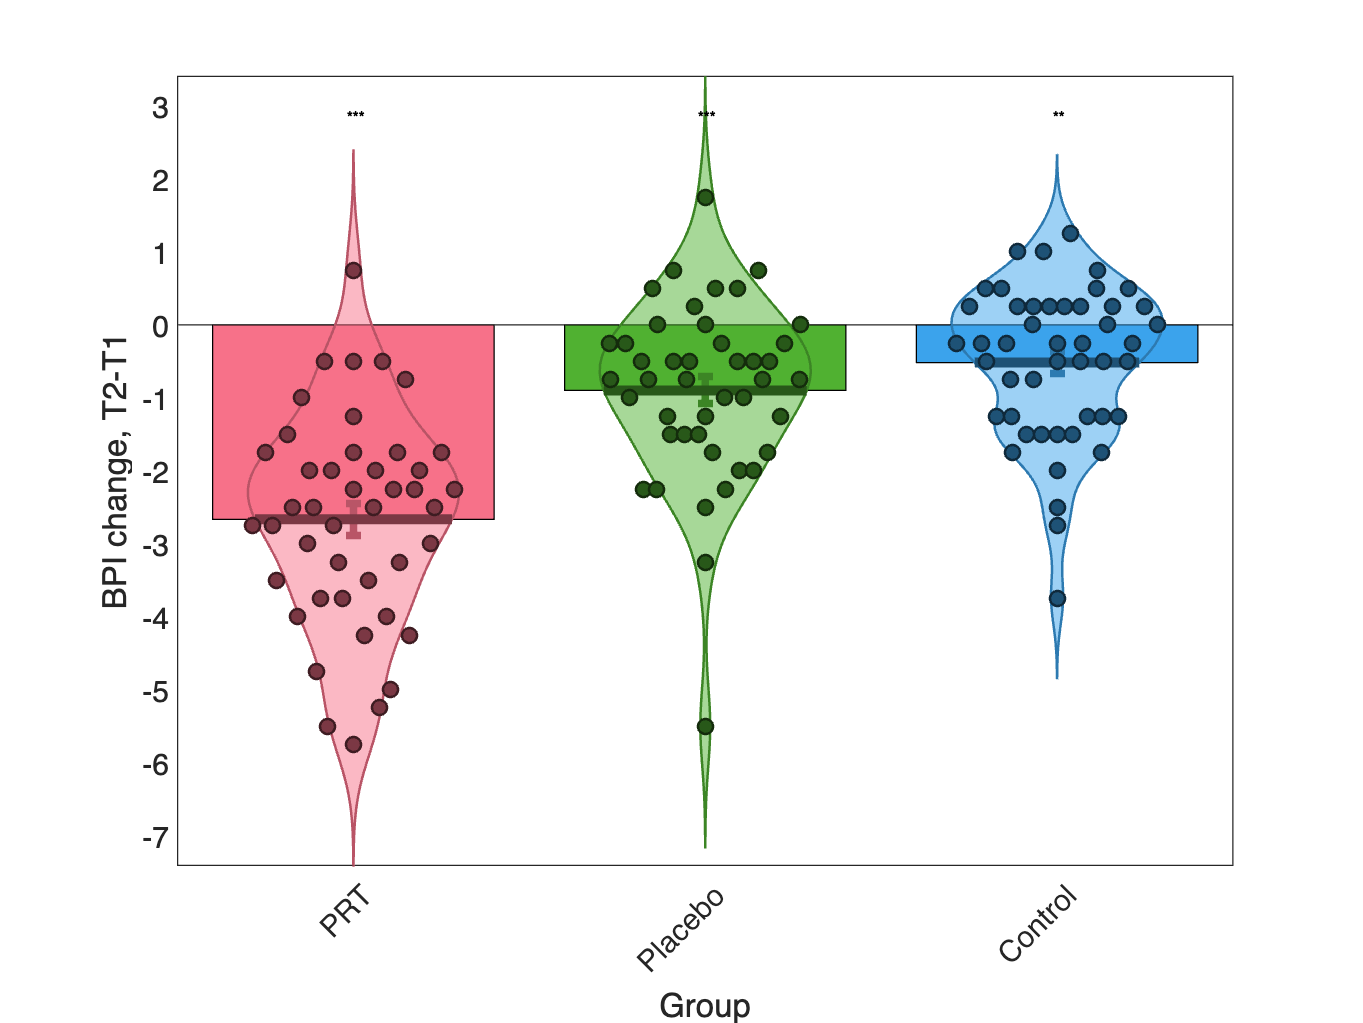

ylabel('BPI change, T2-T1')
xlabel('Group');

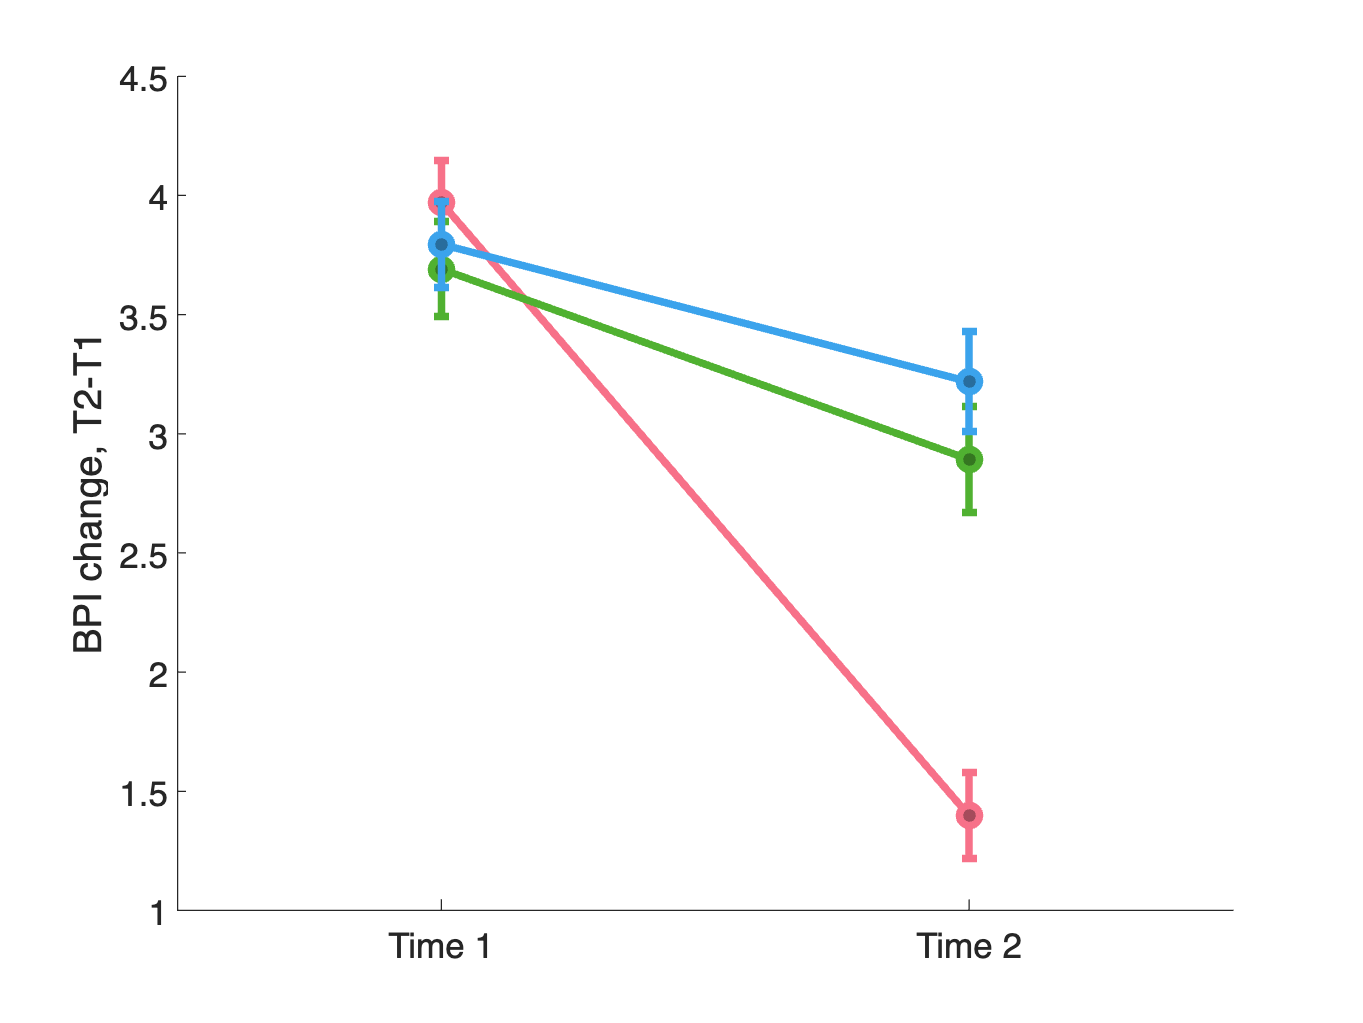


create_figure('Lines');
line1 = lineplot_columns([prt.BPI_Time1 prt.BPI_Time2], 'w', 3, 'color', colors{1}, 'markerfacecolor', colors{1}./1.5);
line2 = lineplot_columns([placebo.BPI_Time1 placebo.BPI_Time2], 'w', 3, 'color', colors{2}, 'markerfacecolor', colors{2}./1.5);
line3 = lineplot_columns([control.BPI_Time1 control.BPI_Time2], 'w', 3, 'color', colors{3}, 'markerfacecolor', colors{3}./1.5);
ylabel('BPI change, T2-T1')
set(gca, 'XLim', [0.5 2.5], 'XTick', 1:2, 'XTickLabel', {'Time 1' 'Time 2'})

### Code hygiene

To keep the code clean, here are some things I attempted to do:

- Use descriptive names for variables, so that I intuitively know what they mean

- Comment the code to explain key steps, so I can ideally read the code "like a book"

- Print key output to check each step

- Include text to label and explain the output and its interpretation

To keep the code clean, here are some things I did NOT do:

- I did NOT re-use variable names so that the same variable refers to different content at different points in the script

- I did NOT print a bunch of extraneous output

- I did NOT include long code blocks with calculations in the main script (I would create a subfunction for these).